# Temperature Parameter Extraction

clear all
pwd

ans = 'C:\Users\jekir\Documents\GitHub\FYP_Battery\Matlab\Learning\Dans_Data_Extraction'

load("..\..\..\cycle_exports\MOLI_28\MOLI_cycle_15.mat")
p = solution_unbound.p;

current_lut = @(t) interp1(tt, u1, t, 'linear', 'extrap');
yactual_lut = @(t) interp1(tt, y, t, 'linear', 'extrap');
[t_sim, y_sim] = ode45(@(t, y) dynamics(t, y, p, current_lut), [0 tt(end)], [1; 0.05]);
x1=y_sim(:,1);x2=y_sim(:,2); R0 = p(end-1);
u2=current_lut(t_sim);
polyss = flip(p(1:end-4));
OCV_x = polyval(polyss,x1);
voltage_model=OCV_x + x2 + R0.*u2;
figure
plot(t_sim,voltage_model)
hold on
plot(t_sim,yactual_lut(t_sim))
title("Sim vs Real Voltage response")


%Heat generation is approxomated as the Vout-Ocv * I, which can be
%numerically found from the combination of states and input. The power out
%over time is as follows:
%dT = Q_heat/mCp - hA/mCp * (T - T_amb)
%dT = Q_heat/mCp - hA/mCp * (T - T_amb)

%Creatingh the table entry for the iddata for the model

Q_heat = (voltage_model - OCV_x).*current_lut(t_sim);
Q_lut = @(tn) interp1(t_sim, Q_heat, tn, 'linear', 'extrap');
temp_lut = @(tn) interp1(tt, tp, tn, 'linear', 'extrap');

greyest_time_sampling = linspace(t_sim(1),t_sim(end),1500);

% Sample the heat generation data for the specified time points
U_sampled = Q_lut(greyest_time_sampling);
%Current_sampled = current_lut(greyest_time_sampling);
Temp_sampled = temp_lut(greyest_time_sampling);

Data = array2table([U_sampled', Temp_sampled'],"VariableNames",["u1","y"]);
Data_ts = table2timetable(Data,"RowTimes",seconds(greyest_time_sampling));
smodle = iddata(Data_ts,'Name','Temperature Generation')

smodle = Time domain data set with 1500 samples.
Sample time: 9.61558 seconds           
Name: Temperature Generation           
                                       
Outputs      Unit (if specified)       
   y                                   
                                       
Inputs       Unit (if specified)       
   u1                                  
                                       


plot(greyest_time_sampling,Temp_sampled)

mCp = 100;
hA = 0.2;
parameters = {'specificheat*mass',mCp;'conduction*length',hA};
init_sys = idgrey(@TempFnc,parameters,'c');

opt = greyestOptions('Focus','simulation');
sys = greyest(smodle,init_sys, opt)


sys =
  Continuous-time linear grey box model defined by @TempFnc function:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1
   x1  -0.001164
 
  B = 
             u1
   x1  0.006272
 
  C = 
      x1
   y   1
 
  D = 
      u1
   y   0
 
  K = 
       y
   x1  0
 
  Model parameters:
   specificheat*mass = 159.4
   conduction*length = 0.1856
 
Parameterization:
   ODE Function: @TempFnc
   Disturbance component: none
   Initial state: 'auto'
   Number of free coefficients: 2
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                              
Estimated using GREYEST on time domain data "Temperature Generation".
Fit to estimation data: 57.08%                                       
FPE: 0.07719, MSE: 0.07698                                           
 


res = getpvec(sys)

res =   159.4467
    0.1856


mCp = res(1)

mCp = 159.4467

hA = res(2)

hA = 0.1856

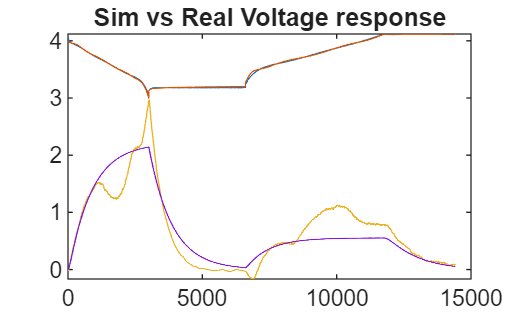

simulated_temp = lsim(sys, Q_lut(greyest_time_sampling)',greyest_time_sampling);
plot(greyest_time_sampling,simulated_temp)
hold on


s1 = 2.3

s1 = 2.3000

s2 = 3.5

s2 = 3.5000

s3 = 5.3

s3 = 5.3000

t_new = linspace(0,3000,800)

t_new = 1.0e+03 *

         0    0.0038    0.0075    0.0113    0.0150    0.0188    0.0225    0.0263    0.0300    0.0338    0.0375    0.0413    0.0451    0.0488    0.0526    0.0563    0.0601    0.0638    0.0676    0.0713    0.0751    0.0788    0.0826    0.0864    0.0901    0.0939    0.0976    0.1014    0.1051    0.1089    0.1126    0.1164    0.1202    0.1239    0.1277    0.1314    0.1352    0.1389    0.1427    0.1464    0.1502    0.1539    0.1577    0.1615    0.1652    0.1690    0.1727    0.1765    0.1802    0.1840


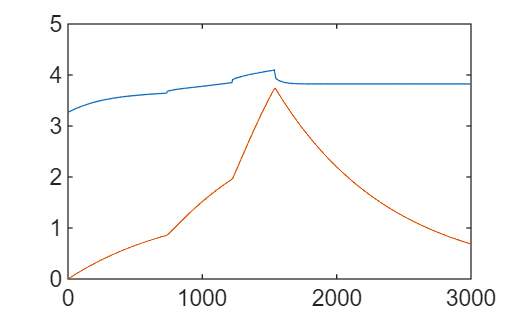

u1=cc3(p,s1,s2,s3,t_new);

current_lut = @(t) interp1(t_new, u1, t, 'linear', 'extrap');
[t_sim, y_sim] = ode45(@(t, y) dynamics(t, y, p, current_lut), [0 t_new(end)], [0; 0.05]);
x1=y_sim(:,1);x2=y_sim(:,2); R0 = p(end-1);
u2=current_lut(t_sim);
polyss = flip(p(1:end-4));
OCV_x = polyval(polyss,x1);
voltage_model=OCV_x + x2 + R0.*u2;
figure
plot(t_sim,voltage_model)
hold on


Q_heat = (voltage_model - OCV_x).*current_lut(t_sim);
Q_lut = @(tn) interp1(t_sim, Q_heat, tn, 'linear', 'extrap');

greyest_time_sampling = linspace(t_sim(1),t_sim(end),1500);

simulated_temp = lsim(sys, Q_lut(greyest_time_sampling)',greyest_time_sampling);
plot(greyest_time_sampling,simulated_temp)
hold on




%% Model for irr only
function [A,B,C,D] = TempFnc(mCp,hA,Ts,aux)
% ODE function for computing state-space matrices as functions of parameters
A = [-hA/mCp];
B = [1/mCp];
C = eye(1);
D = [0];
end